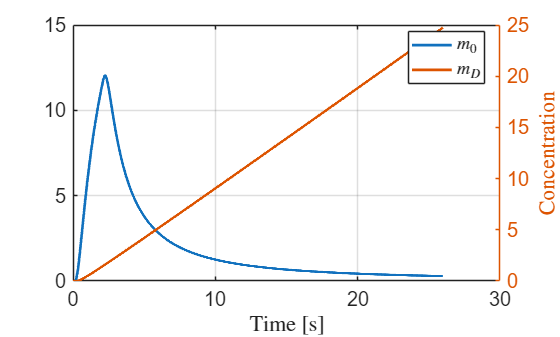

clc;
clear;
close all;

fontsize = 15;

%% =========================
% Parameters
% ==========================

% Fast branch: production of m_F from m_0
pf      = 1;
kf      = 2;
Kf      = 0.5;
kf_deg  = 0;

% Slow branch: production of m_S from m_0
ps      = 0.01;
kS_prod = 2;
KS_prod = 0.5;
kS_deg  = 0;

% Differentiator output m_D
kD_prod = 1;
KD      = 0.2;
nD      = 1;
kD_deg  = 0;      % keep 0 first, since your pulse behavior worked like this

% Counter block
% rC : mD -> m1
VmaxC   = 1.0;    % maximum rate for counter production
KMC     = 0.05;   % Michaelis constant for mD -> m1

% rI1 : m1 + mS -> sink
k1S     = 5.0;    % reset/removal of m1 by mS

% rI2 : mD + mS -> sink
kDS     = 10.0;   % protection reaction: mD consumes mS

% Communication channel parameters
M_0 = 1e4;
D   = 66e-13;     % Diffusion coefficient
d   = 5e-6;       % distance

Tp = 2;           % pulse duration [s]
Ts = 0.01;        % sampling time [s]
fs = 1/Ts;

sequence = [1 0 0 0 0 0 0 0 0 0 0 0 0];

% Receiver radius
r   = 0.15e-6;
VRx = 4/3*pi*r^3;

%% =========================
% Time and transmitted signal
% ==========================

samples_per_pulse = floor(Tp * fs);
total_samples     = length(sequence) * samples_per_pulse;

t = (0:total_samples-1)' / fs;

mTx = repelem(sequence, samples_per_pulse)' * M_0;

%% =========================
% Diffusion channel
% ==========================

t_h = t;
t_h(1) = 1/fs;

h = VRx ./ (4*pi*D*t_h).^(3/2) .* exp(-d^2 ./ (4*D*t_h));

m0 = conv(h, mTx);
m0 = m0(1:length(t));

%% =========================
% State initialization
% ==========================

N  = length(t);

mF = zeros(N,1);   % fast metabolite
mD = zeros(N,1);   % differentiator output
mS = zeros(N,1);   % slow/reset metabolite
m1 = zeros(N,1);   % counter output

% Optional bookkeeping of reaction rates
vC   = zeros(N,1); % rC
vI1  = zeros(N,1); % rI1
vI2  = zeros(N,1); % rI2
prodD = zeros(N,1);

mF(1) = 0;
mD(1) = 0;
mS(1) = 0;
m1(1) = 0;

%% =========================
% Discrete-time simulation
% ==========================

for n = 1:N-1

    dt = t(n+1) - t(n);

    % -----------------------------------
    % 1) Fast branch m_F
    % rF : m0 -> mF
    % -----------------------------------
    prod_F = pf * kf * ( m0(n) / (Kf + m0(n)) );
    deg_F  = kf_deg * mF(n);

    mF(n+1) = mF(n) + dt * ( prod_F - deg_F );
    mF(n+1) = max(mF(n+1), 0);

    % -----------------------------------
    % 2) Slow branch m_S
    % rS : m0 -> mS
    % -----------------------------------
    prod_S = ps * kS_prod * ( m0(n) / (KS_prod + m0(n)) );
    deg_S  = kS_deg * mS(n);

    % NOTE:
    % rI2 will also consume mS, but we add that later after evaluating vI2
    mS_temp = mS(n) + dt * ( prod_S - deg_S );
    mS_temp = max(mS_temp, 0);

    % -----------------------------------
    % 3) Differentiator output m_D
    % rd : mF -> mD
    % -----------------------------------
    act_D = (mF(n)^nD) / (KD^nD + mF(n)^nD);
    prodD(n) = kD_prod * act_D;

    % For now, keep the same pulse-forming differentiator behavior
    mD_temp = mD(n) + dt * ( prodD(n) - kD_deg * mD(n) );
    mD_temp = max(mD_temp, 0);

    % -----------------------------------
    % 4) Counter reactions
    % rC  : mD -> m1
    % rI1 : m1 + mS -> sink
    % rI2 : mD + mS -> sink
    % -----------------------------------

    % Use current-time values for reaction rates
    vC(n)  = VmaxC * mD(n) / (KMC + mD(n));   % Michaelis-Menten production of m1
    vI1(n) = k1S * m1(n) * mS(n);             % m1 removed by mS
    vI2(n) = kDS * mD(n) * mS(n);             % mD consumes mS (protection)

    % -----------------------------------
    % 5) Update mD with rI2
    % If you want mD to be consumed stoichiometrically by rI2:
    % -----------------------------------
    mD(n+1) = mD_temp - dt * vI2(n);
    mD(n+1) = max(mD(n+1), 0);

    % -----------------------------------
    % 6) Update mS with rI2
    % -----------------------------------
    mS(n+1) = mS_temp - dt * vI2(n);
    mS(n+1) = max(mS(n+1), 0);

    % -----------------------------------
    % 7) Update m1 with rC and rI1
    % -----------------------------------
    m1(n+1) = m1(n) + dt * ( vC(n) - vI1(n) );
    m1(n+1) = max(m1(n+1), 0);

end

% fill last samples for plotting
prodD(end) = prodD(end-1);
vC(end)    = vC(end-1);
vI1(end)   = vI1(end-1);
vI2(end)   = vI2(end-1);

%% =========================
% Plot 1: m0 and mD
% ==========================

figure;
plot(t, m0, 'LineWidth', 2); hold on;
yyaxis right
plot(t, mD, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration', 'Interpreter', 'latex');
legend({'$m_0$', '$m_D$'}, 'Interpreter', 'latex', 'Location', 'best');
set(gca, 'FontSize', fontsize);
grid on;


%% =========================
% Plot 2: mD, mS, m1
% ==========================

figure;
% plot(t, mD, 'LineWidth', 2); hold on;
% plot(t, mS, 'LineWidth', 2);
plot(t, prodD, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration', 'Interpreter', 'latex');
legend({'$m_D$', '$m_S$', '$m_1$'}, 'Interpreter', 'latex', 'Location', 'best');

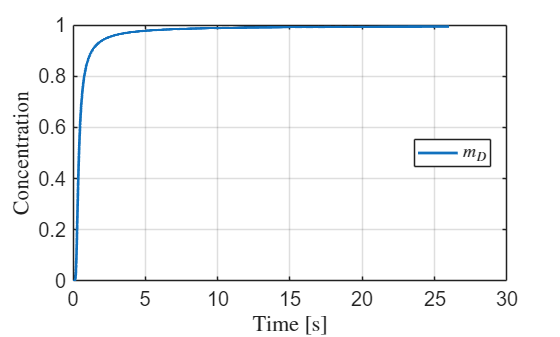

set(gca, 'FontSize', fontsize);
grid on;

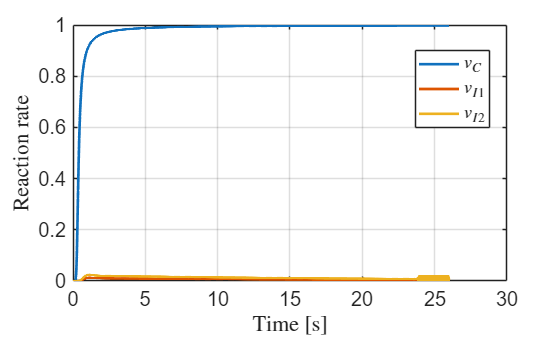


%% =========================
% Plot 3: reaction rates
% ==========================

figure;
plot(t, vC, 'LineWidth', 2); hold on;
plot(t, vI1, 'LineWidth', 2);
plot(t, vI2, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Reaction rate', 'Interpreter', 'latex');
legend({'$v_C$', '$v_{I1}$', '$v_{I2}$'}, 'Interpreter', 'latex', 'Location', 'best');
set(gca, 'FontSize', fontsize);
grid on;